cfgVHT = wlanVHTConfig('ChannelBandwidth','CBW20');
y = wlanLSTF(cfgVHT);
size(y)

ans =    160     1


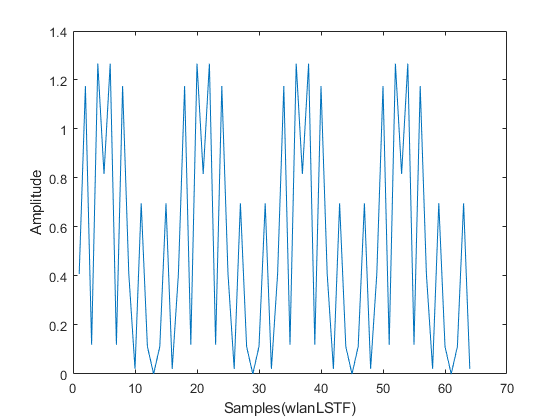

plot(abs(y))
xlabel('Samples(wlanLSTF)')
ylabel('Amplitude')

seqShort = sqrt(1/2)*[0;0;1+j;0;0;0;-1-j;0;0;0;1+j;0;0;0;-1-j;
                0;0;0;-1-j;0;0;0;1+j;0;0;0;0;0;0;0;-1-j;
                0;0;0;-1-j;0;0;0;1+j;0;0;0;1+j;0;0;0;1+j;
                0;0;0;1+j;0;0];
           
STFpriorIFFT = [zeros(6,1);seqShort;zeros(5,1)];

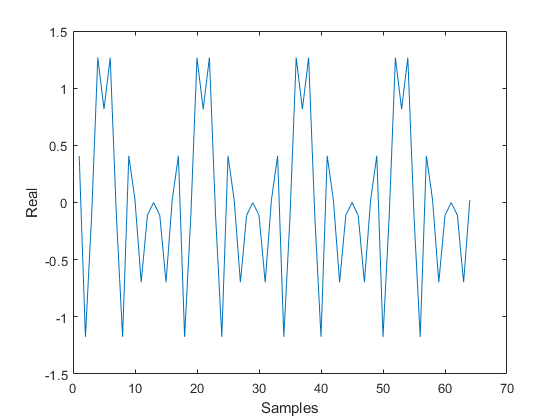

k = -32:1:31;
k =  k'; 
STFifft = zeros(64,1);

for nn = 1:64       
        yy = STFpriorIFFT .* exp(j*2*pi*k*(nn-1)/64);
        STFifft(nn) = (1/sqrt(12)) * sum(yy) ;
end
plot(real(STFifft));
xlabel('Samples')
ylabel('Real')

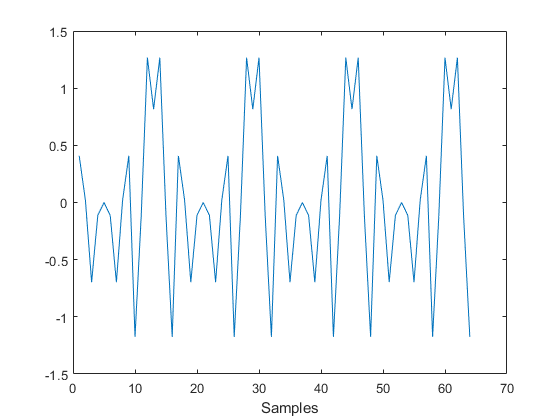


plot(imag(STFifft));
xlabel('Samples')

ylabel('Imaginary')

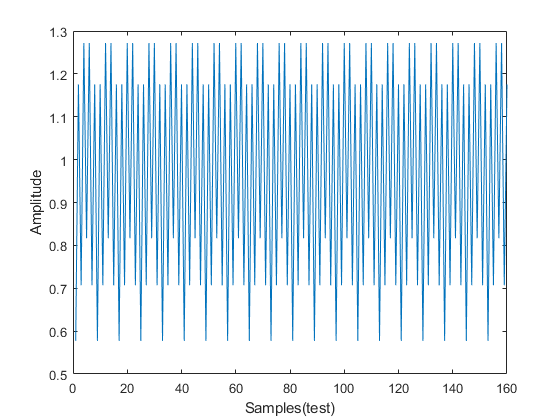

STFifft_double = [STFifft;STFifft];
STFifft_full = [STFifft_double(97:128);STFifft_double];

plot(abs(STFifft_full))
xlabel('Samples(test)')
ylabel('Amplitude')

% FFT 
k2 = 0:1:63;
k2 = k2';
STFfft = zeros(64,1);

for kk = 1:64       
        yy =  sqrt(12) *STFifft .* exp(-j*2*pi*(kk-33)*k2/64);
        STFfft(kk) = 1/64 *  sum(yy) ;
end

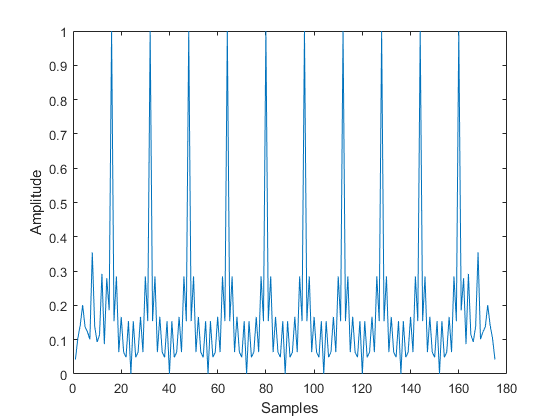

% STFcorr = zeros(160,1);
% STFcorr_append = [STFifft_full;zeros(15,1)];
% for ss = 1:1:160
%     STFcorr(ss) = sum(STFcorr_append(ss:16+ss-1).*STFifft(1:16));
% end
% 
% plot(abs(STFcorr))
% 
% xlabel('Samples')
% ylabel('Amplitude')


[r,lags] = xcorr(STFifft_full,STFifft(1:16));

plot(abs(r(145:319))/max(abs(r)))
% plot(abs(r))

xlabel('Samples')
ylabel('Amplitude')